
Single objective optimization:
2 Variable(s)

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100          -61.58           27.16        0
    2              147          -98.99           12.29        0
    3              194          -108.5           1.876        0
    4              241          -108.5           4.079        1
    5              288          -127.6           -10.6        0
    6              335          -127.6          -10.02        1
    7              382          -127.6          -21.13        2
    8              429          -143.7          -23.05        0
    9              476          -143.7          -10.14        1
   10              523          -143.7          -22.02        2
   11      

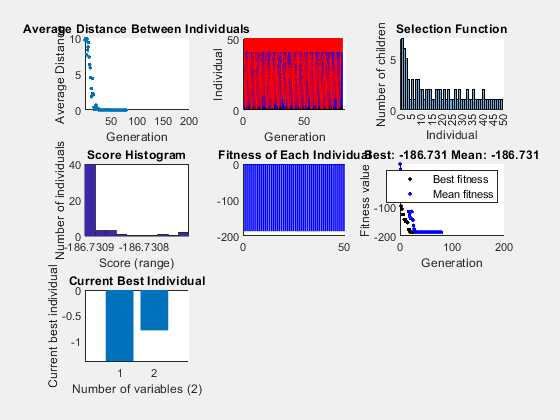

% Set nondefault solver options
options = optimoptions("ga","Display","iter","PlotFcn",["gaplotdistance",...
    "gaplotgenealogy","gaplotselection","gaplotscorediversity",...
    "gaplotscores","gaplotbestf","gaplotbestindiv"]);

% Solve
[solution,objectiveValue] = ga(fun,nvar,[],[],[],[],repmat(-10,nvar,1),...
    repmat(10,nvar,1),[],[],options);


% Clear variables
clearvars options


nvar = 2;
fun = @Shubert2_fun;
% Creation function 'gacreationlinearfeasible' and Mutation function
% 'mutationpositivebasis' gave best result so far, with -186.7304 at
% [-0.8008, 4.8581]. Global minima is -186.730909